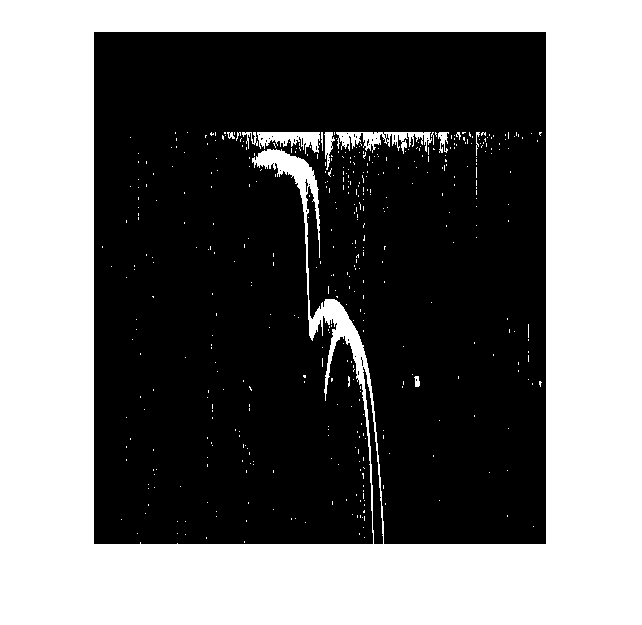

%function FreqFilImg = Freqfilt(img)
    
    imgVar_ = img;
    imgVar_ = imgVar_(imgVar_~=0);
    
    F=fft2(img);
    
    %figure; imagesc(log10(abs(F)));
    figure; imagesc(fftshift(log10(abs(F))+1));
    

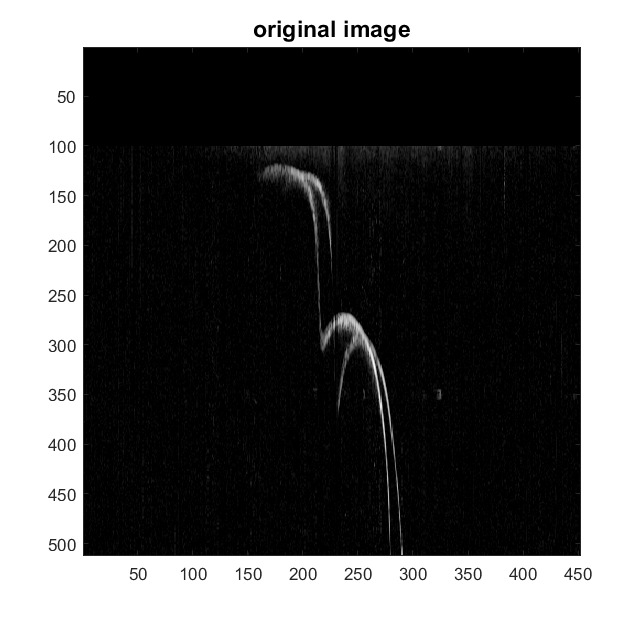

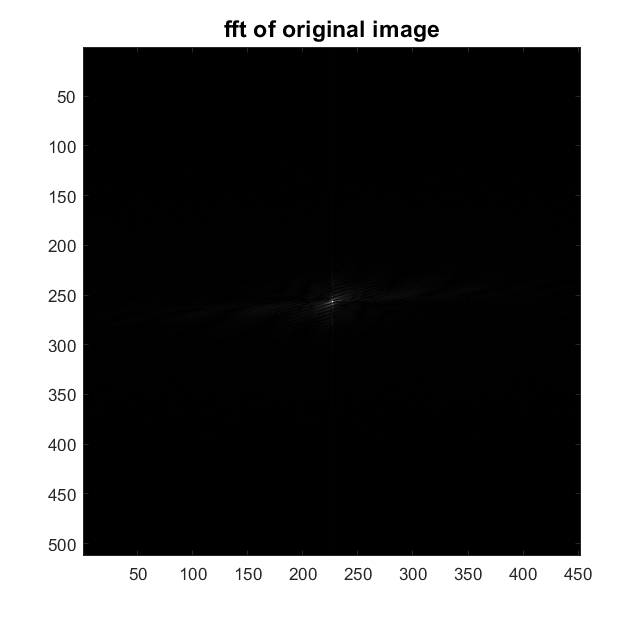

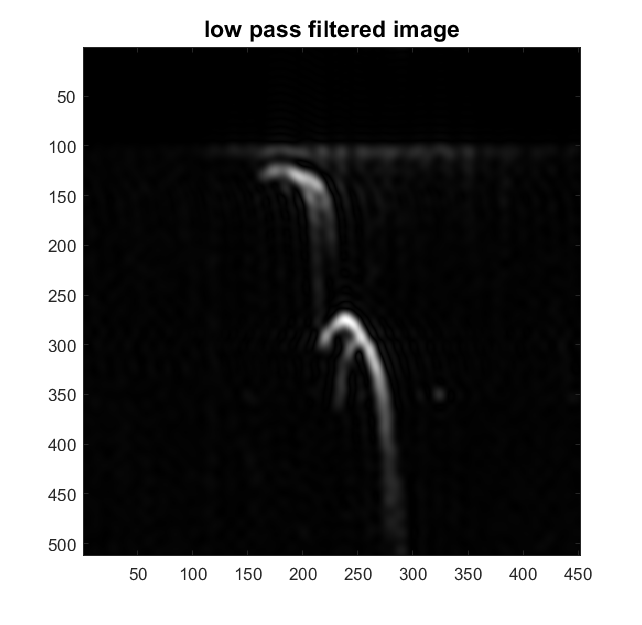

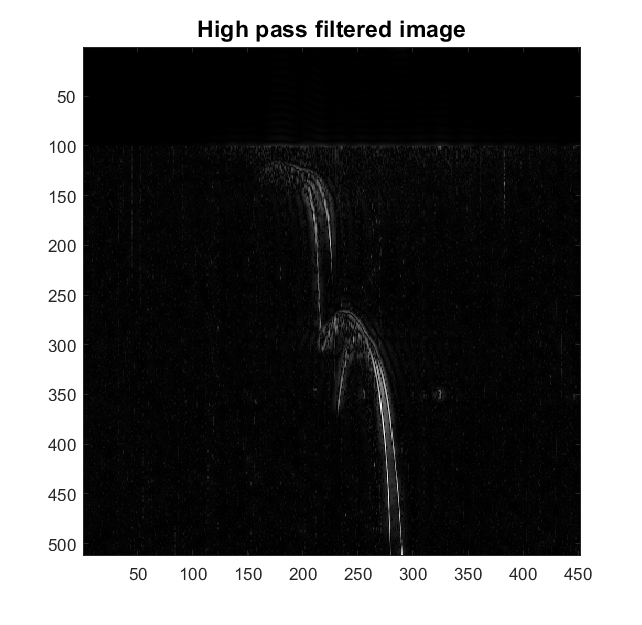

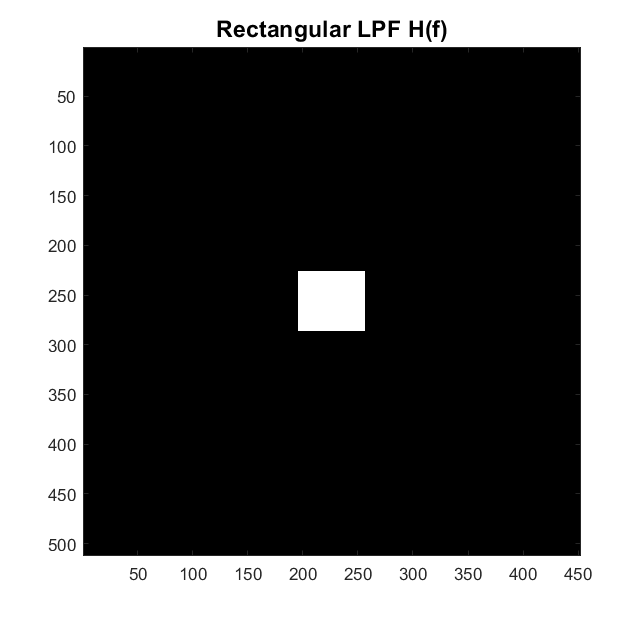

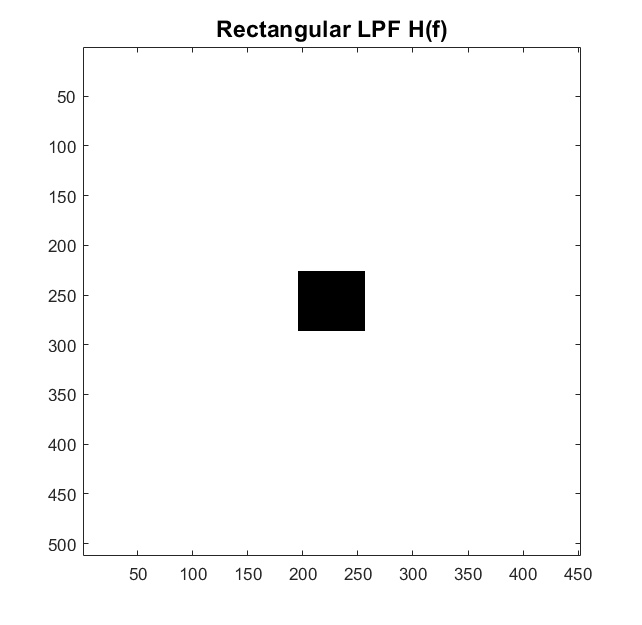

    A = zeros(10);

    A(3:7,3:7) = ones(5);
    
    
    mesh(A)
    
    r = 4;
    [X,Y,Z] = cylinder(r, 20);
    h = 20;
    Z = Z*h;
    surf(X,Y,Z)
    
    [f1,f2] = freqspace(452,'meshgrid');
    
    r = sqrt(f1.^2 + f2.^2);
    
    Hd = zeros(452); 
    Hd(r>0.5) = 1;
    
    colormap(parula(64))
    mesh(f1,f2,Hd)
    
    win = fspecial('gaussian',452,2);
    win = win ./ max(win(:));
    
    mesh(win)
    
    h = fwind2(Hd,win);
    
    freqz2(h)
    
%     FreqFilImg = imgaussfilt(img, std(imgVar_),'FilterDomain',"frequency");
    
    F=fft2(imgDen_1);
    
    %figure; imagesc(log10(abs(F)));
    figure; imagesc(fftshift(log10(abs(F))+1));

    %end
    
    %inpict = im2double(rgb2gray(imread('linenoise.jpg')));
    figure, imagesc(imgThresh)
    figure; imagesc(fftshift(log10(abs(fft2(imgThresh)))+1)), colorbar;
    
    outpict = medfilt2(iIonDenProjFilt, [4, 3]);
    imshowpair(imgThresh, outpict,'montage')
    %outpict = imadjust(outpict,[0.15 0.85]);
    figure; imagesc(fftshift(log10(abs(fft2(outpict)))+1)), colorbar;
    
    figure, imagesc(outpict)